# Demonstração da DopplerLib

## Bibliotecas e Funções

- **LibDoppler **é a pasta com as funções usadas para cálculo da velocidade a partir da velocidade doppler, entre elas: `calculate_vel`, `getObservation`, `getObservationTDCP`.

- **LibGnss **é a pasta com funções associadas a leitura e processamento de dados GNSS.

- **ExampleCalculatingVel** tem funções auxiliares para carregar os dados de forma direta (`readData` e `selectGpsData`) 

clear
addpath("LibDoppler\")
addpath("LibGnss\")
addpath("ExampleCalculatingVel\")

## Dados

Os dados são indexados pela data e estão presentes no caminho `Data/dd_mm_yyyy`

`readData: `É uma função auxiliar responsável por carregar os dados

- `rover.obs` e `rover.nav`

- `ground.obs` e `ground.nav`

- `rover.pos`

`selectGpsData`: Seleciona dados da constelação GPS e agrupa em uma struct chamada de `gpsData`

dataPath = "Data/30_07_2021/";
readData;
selectGpsData;
Vpos = diff(posData(:, 2:4));

## Processar dados

Durante o processamento de dados as velocidades são computadas para cada leitura do GNSS.

Alocando espaço...

times = unique(gpsData.roverObs(:, 2));
n = length(times);
V_RD = zeros(3, n);
V_TDCP = zeros(3, n);
T = zeros(1, n);
res = zeros(1, n);

Obtém uma observação específica para o modo **TDCP (Time-Differenced Carrier-Phase)**.

São levados em conta os seguintes critérios:

- Leitura de fase e doppler devem ser diferentes de 0

- Os dados do mesmo satélite devem estar disponíveis em $t_{k-1$, $t_k$ e $t_{k+1}$

Além disso, o desvio doppler no instante $k$, de cada satélite, é calculado a partir da fórmula


$$d_k = -\frac{\Phi_{k+1} - \Phi_{k-1}}{2\Delta t}$$
 

sendo $\Delta t$ o período de medição.

N = n-1;
tic
for k = 2:N
    if times(k) == 481621
        fprintf("");
    end
    [V_TDCP(:, k), res(k), T(k)] = calculate_velTDCP(k, posData, gpsData, Vpos);
    [V_RD(:, k), ~, ~] = calculate_velRD(k, posData, gpsData);

    if mod(k, round(.1*n)) == 0
        fprintf("\b\b\b%.0f%%", k/N*100);
    end 
end

100%

toc

Elapsed time is 21.488673 seconds.


## Plotando Resultados

Para fins de comparação, cálculo as variações das posições *xyz* do arquivo `.pos`

Plotando ambos resultados juntos

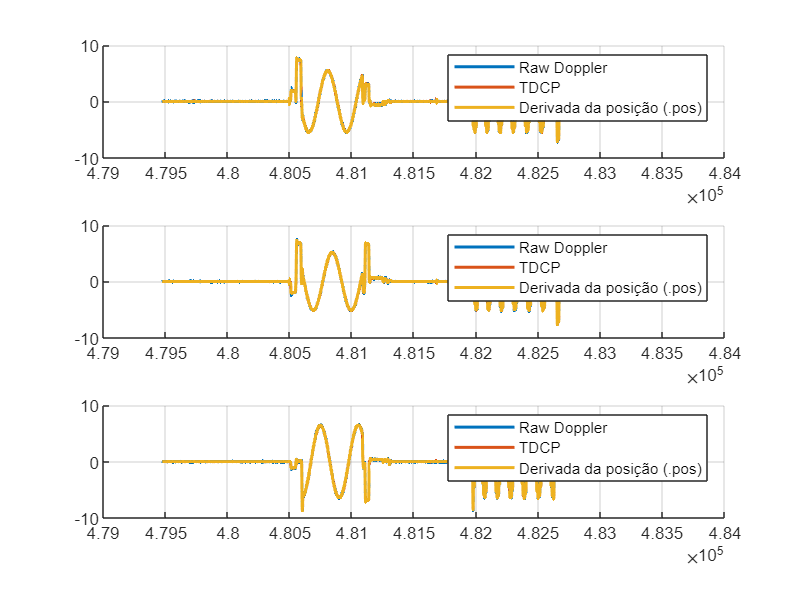

figure
for j = 1:3
    subplot(3, 1, j)
    hold on
    plot(T(2:end-1), V_RD(j, 2:end-1), DisplayName="Raw Doppler", LineWidth=1.5);
    plot(T(2:end-1), V_TDCP(j, 2:end-1), DisplayName="TDCP", LineWidth=1.5);
    plot(posData(1:end-1, 1), Vpos(:, j), DisplayName="Derivada da posição (.pos)", LineWidth=1.5)
    legend()
    grid()
end

### Maior resíduo produzido pelo LS

% figure
% plot(T(2:end-1), res(2:end-1), 'x')
% grid()

### Diferença entre (v_RD x v_TCDP) ou (v_TCDP x dp/dt)

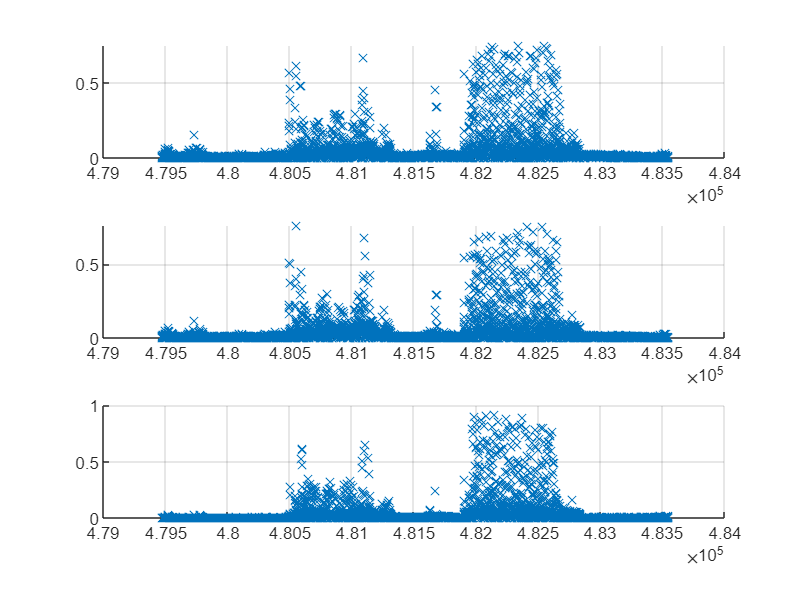

figure
for j = 1:3
    subplot(3, 1, j)
    hold on
    %plot(T(2:end-1), abs(V_RD(j, 2:end-1) - V_TDCP(j, 2:end-1)), 'x')
    plot(T(2:end-1), abs(Vpos(2:end-1, j)' - V_TDCP(j, 2:end-1)), 'x')
    grid()

end